# Sampling from Probability Distributions and Random Number Generation

## Elementary Example

Form the theoretical distribution to sample from

f=[0.2,0.5,0.3];

Collect the sample of 25 values taken from the set (0,1,2) distributed according to f.

X=randsample(0:2,25,true,f)

Visualize the sample with a relative frequency histogram and compare it to the theoretical histogram for $f$.

figure(1)
histogram(X,[-0.5:1:2.5],'Normalization','pdf')
hold on
x=0:length(f)-1;
bar(x,f)
xticks([0,1,2])
hold off
legend('Sampled Data','Theoretical Distribution','Location','northwest')

## Sampling from a known distribution

Randomly sample 25 numbers from the binomial distribution with the given parameters

n=7;
p=0.67;
X=binornd(n,p,1,25)

Visually compare the sample to the theoretical distribution.

figure(2)
histogram(X,[-0.5:1:n+0.5],'Normalization','pdf')
hold on
bar(0:n,binopdf(0:n,n,p))
xticks([0:n])
hold off
legend('Sampled Data','Binomial Distribution','Location','northwest')

## Implementing Your Own LCG

For those who are curious, we can revisit our first example of sampling from the three state distribution $f$, but we will approach it without making use of Matlab's built-in randsample function.  We'll implement our own Linear Congruential Generator to select random indices to be used for sampling values from a population we build to be distributed according to the distribution $f$.

Set up the population to sample from and define the sample size

N=1000; % Population Size
K=25;   % Sample Size


% Form the population to sample from
f=[0.2,0.5,0.3];
D=[];
for i=0:length(f)-1
    D=[D i*ones(1,round(f(i+1)*N))];
end

LCG algorithm for generating a set of K random indices ranging from 1 to N. These represent a uniformly distributed, random sample (taken with replacement) from the set $\{1,2,3,\dots,N\}$.

Initialize the LCG: $I_{n+1}\equiv(a I_n +c)\;\mathrm{mod }\;m$

m=2^31-1;   % modulus
a=48271;    % coefficient
c=0;        % step

I=41;   % Seed 
I=I*ones(1,K);

for i=1:K-1
    I(i+1)=mod(a*I(i)+c,m);
end
I=mod(I,N)+1

I =     42   112   614   799   826   449   475    15   354   862   662   271   254   747   759   906   960    85   675   981   663   489   587   489   746


Collect a sample from the population using the randomly generated indices and then build a relative frequency histogram for the sample. Compare the histogram to that of the theoretical distribution $f$.

X=D(I)

X =      0     0     1     2     2     1     1     0     1     2     1     1     1     2     2     2     2     0     1     2     1     1     1     1     2


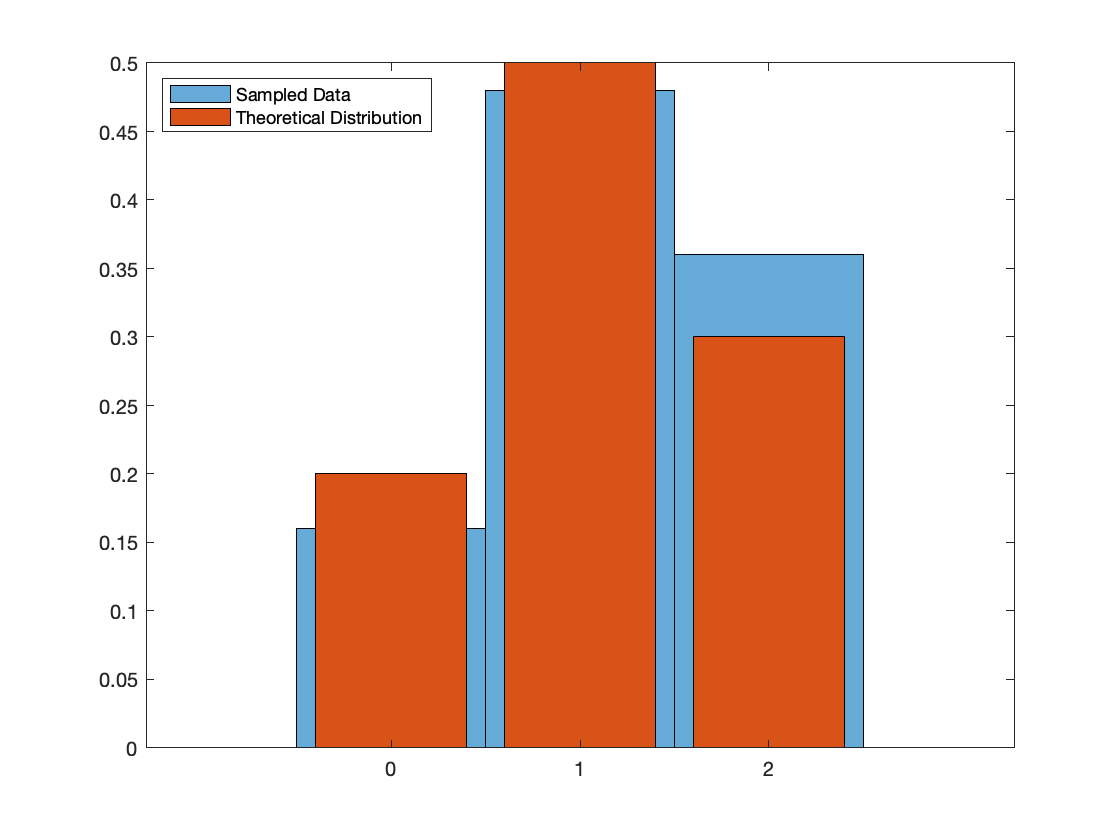

figure(3)
histogram(X,[-0.5:1:2.5],'Normalization','pdf')
hold on
x=0:length(f)-1;
bar(x,f)
xticks([0:2])
hold off
legend('Sampled Data','Theoretical Distribution','Location','northwest')